# Final Project Solution

## Baseline Classifier

Here is our Baseline Classifier, we our using transfer learning on Alexnet to train our images. We used all the images avaible in the Kaggle dataset. We also split the data with 80% being used for training and 20% being used for validation. We then modified our training options to what we thought would give the best possible validation and test accuracy.

% get AlexNet CNN
baselineModel = alexnet;

% set the path to our data folder
dataFolder = './data/train';
% create the variable that will hold our categories
categories = {'cat', 'dog'};

% create our image database 
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');

% read and preprocess the images in the data set to match the input of
% alexnet 
imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

% split the database into a training and validation set, giving 80% to the
% training set and the remaining 20% to the validation set
[trainingSet, validationSet] = splitEachLabel(imds, 0.8, 'randomized');

ans = 2×2 table
    Label    Count
    _____    _____

     cat     10000
     dog     10000


ans = 2×2 table
    Label    Count
    _____    _____

     cat     2500 
     dog     2500 



% Layer transfer
layersTransfer = baselineModel.Layers(1:end-3); % save layers to transfer over
numClasses = 2; % number of classes

% completed layer transfer
layers = [
    layersTransfer % saved layers
    % new fully connected layer with different number of classes
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer % new softmax layer
    classificationLayer]; % new classificaton layer

% set training options for model
options = trainingOptions('sgdm', ...
    'MiniBatchSize',50, ...
    'MaxEpochs',15, ...
    'InitialLearnRate',1e-4, ... 
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',4, ...
    'Verbose',false, ...
    'ExecutionEnvironment',"auto", ...
    'Plots','training-progress');

% train the new network
baselineModelTransfer = trainNetwork(trainingSet,layers,options);

% classify the images in our validation set
ValPred = classify(baselineModelTransfer,validationSet);

ValidationActual = validationSet.Labels;
accuracy = mean(ValPred == ValidationActual); % find validation accuracy
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

### Baseline Classifer Test Images

This code is to use the 1000 images from the Kaggle test dataset, to test the baseline classifier. And make a confusion matrix and ROC curve of Both cat and dog classes from the test images.

% set the path to our data folder
dataFolder = './data/test';
% create the variable that will hold our categories
categories = {'cat', 'dog'};

% create our image database with test images
testimds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');

inputSize = baselineModel.Layers(1).InputSize; % get input image size

% use inputSize & colorPreprocessing to preprocess the images and store in
% an augmented image datastore
augtestimds = augmentedImageDatastore(inputSize(1:2),testimds, "ColorPreprocessing","gray2rgb");

% used classify on baselineModelTransfer to get our test predications
[testPred,testScores] = classify(baselineModelTransfer,augtestimds);
% get the labels for each image to get the actual classification for each
% image
testActual = testimds.Labels;

% mean both to get the accuracy of our model
baseline_TestAccuracy = mean(testPred == testActual);
fprintf("The Test accuracy is: %.2f %%\n", baseline_TestAccuracy * 100);

The Test accuracy is: 97.60 %


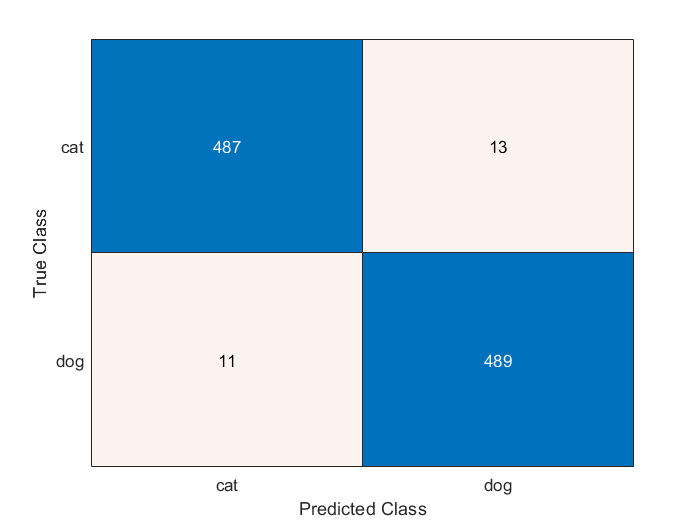


% make confusion matrix out of test images
BaselineConfusionMatrix = confusionchart(testActual,testPred);

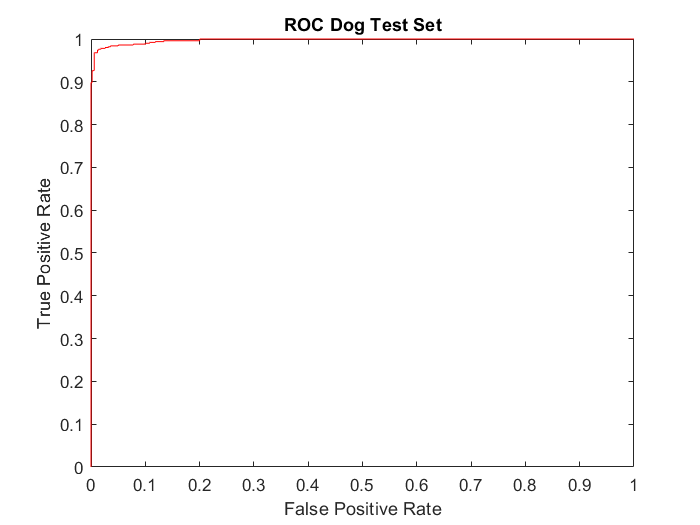


scoresDogTest = testScores(:,2); % get scores for dog images
scoresCatTest = testScores(:,1); % get scores for cat images

% roc graph for dog from test set
[FPRDogTest,TPRDogTest] = perfcurve(testActual,scoresDogTest,'dog');
plot(FPRDogTest,TPRDogTest, 'r-');
title('ROC Dog Test Set');
xlabel('False Positive Rate');
ylabel('True Positive Rate');

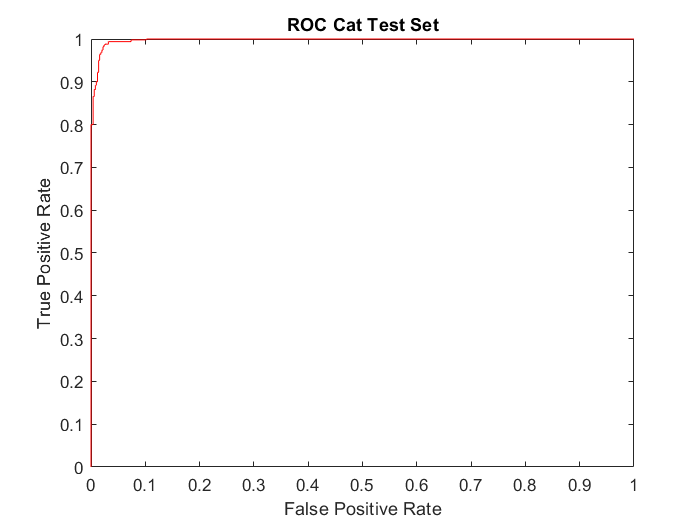


% roc graph for cat from Test Set
[FPRCatTest,TPRCatTest] = perfcurve(testActual,scoresCatTest,'cat');
plot(FPRCatTest,TPRCatTest, 'r-');
title('ROC Cat Test Set');
xlabel('False Positive Rate');
ylabel('True Positive Rate');

## Improved Classifier 1

In Improved Classifier 1, We our also using AlexNet, but with an augmented datastore to help train our images. We are using all of the images in the Kaggle dataset. next we seperated our images into a training and validation set, giving 80% to training and 20% to validation. We created imageAugmenter to store the properties we wanted to change in our training images. We then applied an augmented image datastore to not only add our imageAugmenter to training, but also to preprocess our images in both the training and validation sets. 

% get AlexNet CNN
improvedModel_1 = alexnet;

% set the path to our data folder
dataFolder = './data/train';
% create the variable that will hold our categories
categories = {'cat', 'dog'};

% create an image datastore to hold our images
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');

% seperate into training and validation sets, giving 80% to training and
% remaining to validation set
[trainingSet, validationSet] = splitEachLabel(imds, 0.8, 'randomized');

pixelRange = [-45 45]; % setting our pixel range 
scaleRange = [0.8 1.2]; % setting our scale range
% setting the options for Data Augmentation for our Augmented training data
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandYReflection',true,...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

inputSize = improvedModel_1.Layers(1).InputSize; % get input image size

% create our augmented training and validation set using an Augmented Imgage datastore
% get our Augmented training set with imageAugmenter to augment the images
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

% get our augmented validation set
augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

       20000



        5000



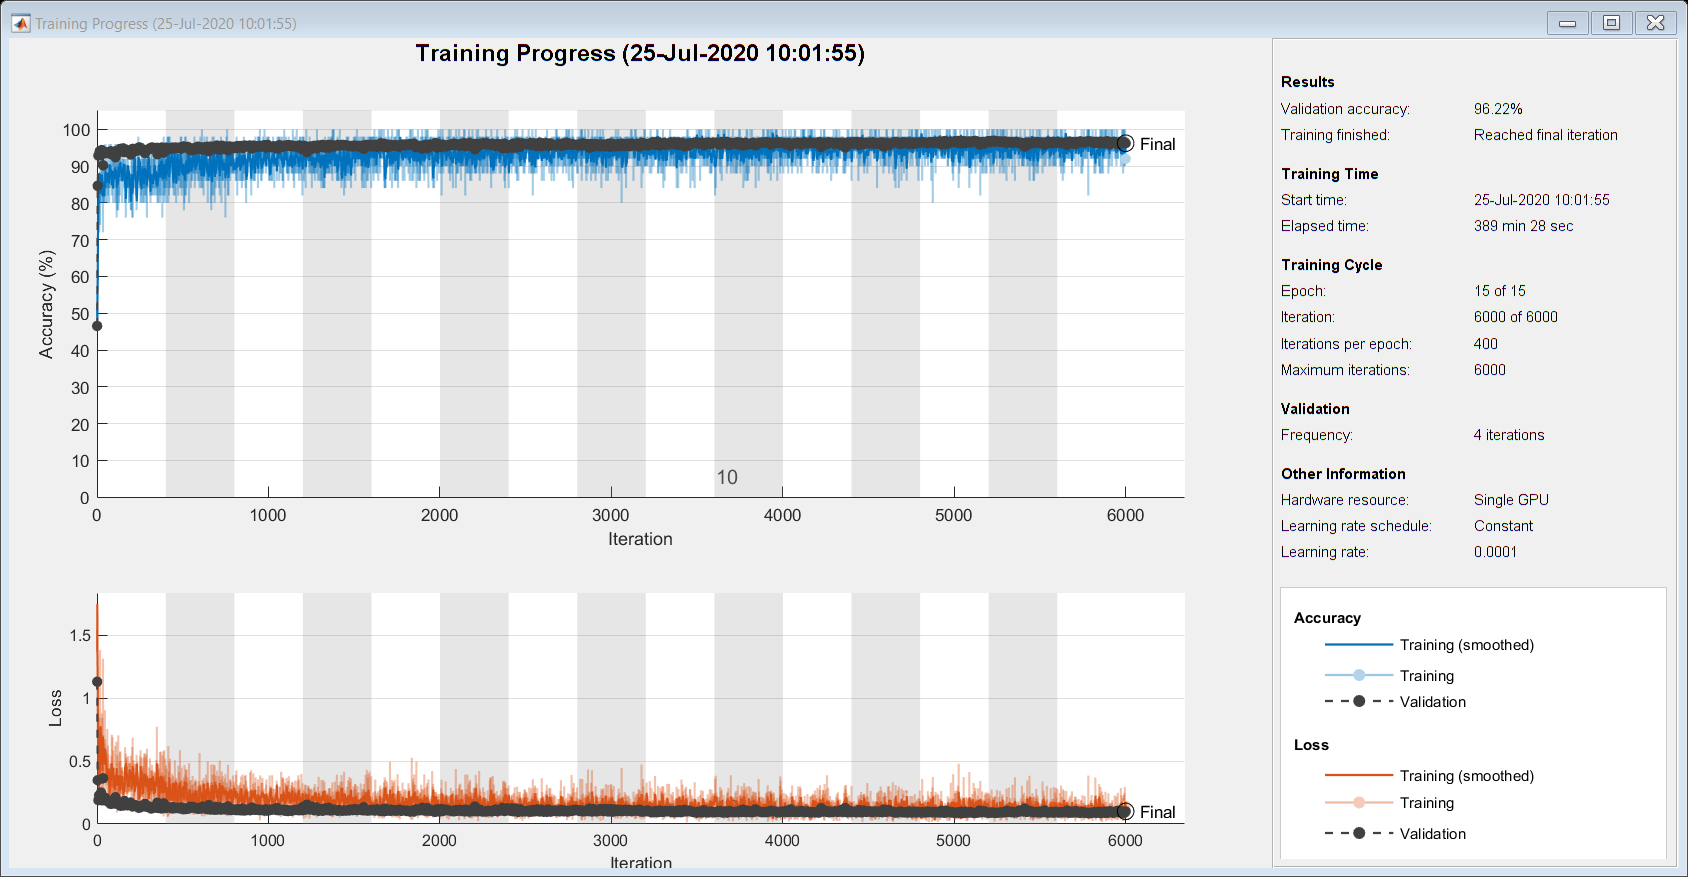


% Layer transfer
layersTransfer = improvedModel_1.Layers(1:end-3);
numClasses = 2; % number of classes

% completed layer transfer
layers = [
    layersTransfer
    % new fcl with different number of classes
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

% set training options for model
options = trainingOptions('sgdm', ...
    'MiniBatchSize',50, ...
    'MaxEpochs',15, ...
    'InitialLearnRate',1e-4, ... 
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',4, ...
    'Verbose',false, ...
    'ExecutionEnvironment',"auto", ...
    'Plots','training-progress');

% train the new network
improvedModelTransfer_1 = trainNetwork(augimdsTrain,layers,options);


% classify the images in our validation set
ValPred = classify(improvedModelTransfer_1,augimdsValidation);

ValidationActual = validationSet.Labels;
accuracy = mean(ValPred == ValidationActual); % get accuracy for validation set
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 96.22 %


### Improved Classifier 1 Test images

This code is to use the 1000 images from the Kaggle test dataset, to test Improved Classifier 1. And make a confusion matrix and ROC curve of Both cat and dog classes from the test images.

% set the path to our data folder
dataFolder = './data/test';
% create the variable that will hold our categories
categories = {'cat', 'dog'};

% create our image database for test images
testimds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');

inputSize = improvedModel_1.Layers(1).InputSize; % get input image size

% use inputSize & colorPreprocessing to preprocess the images and store in
% an augmented image datastore
augtestimds = augmentedImageDatastore(inputSize(1:2),testimds, "ColorPreprocessing","gray2rgb");

% use our model to get the predictions on each image in our test set
[testPred,testScores] = classify(improvedModelTransfer_1,augtestimds);
% get the actual classification of each image
testActual = testimds.Labels;

% get accuracy of our model
improved1_TestAccuracy = mean(testPred == testActual);
fprintf("The Test accuracy is: %.2f %%\n", improved1_TestAccuracy * 100);

The Test accuracy is: 97.20 %


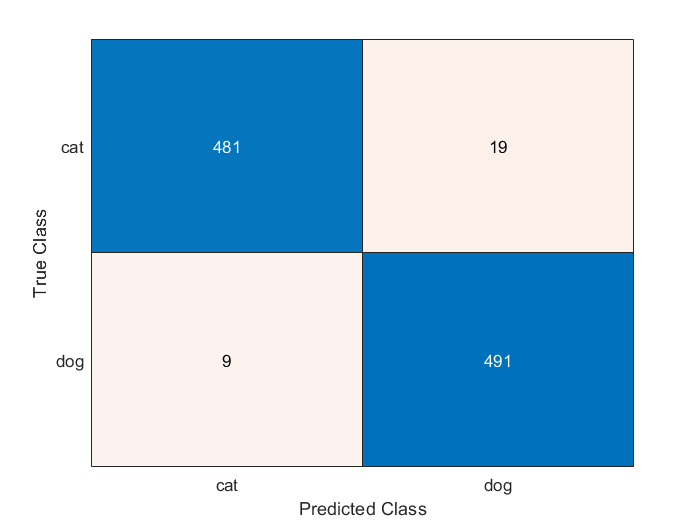


% make a confusion matrix out of the test images
Improved1ConfusionMatrix = confusionchart(testActual,testPred);

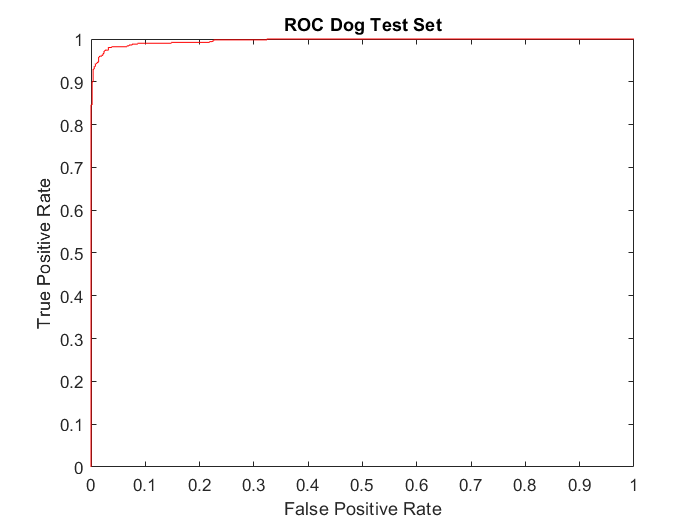


scoresDogTest = testScores(:,2); % get scores for dog images
scoresCatTest = testScores(:,1); % get scores for cat images

% roc graph for dog from test set
[FPRDogTest,TPRDogTest] = perfcurve(testActual,scoresDogTest,'dog');
plot(FPRDogTest,TPRDogTest, 'r-');
title('ROC Dog Test Set');
xlabel('False Positive Rate');
ylabel('True Positive Rate');

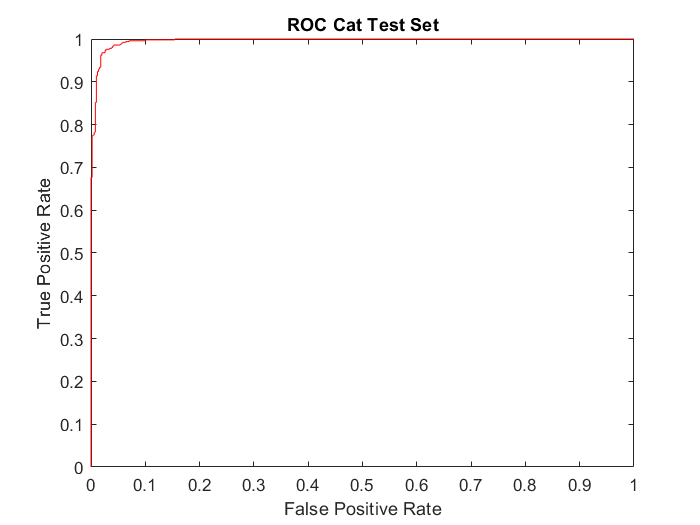


% roc graph for cat from Test Set
[FPRCatTest,TPRCatTest] = perfcurve(testActual,scoresCatTest,'cat');
plot(FPRCatTest,TPRCatTest, 'r-');
title('ROC Cat Test Set');
xlabel('False Positive Rate');
ylabel('True Positive Rate');

## Improved Classifier 2

In Improved Classifier 2, we our using transfer learning on Inception V3 instead of AlexNet, to train our images. In this classifier we are only using 8000 total images to train. These images are put into an image datastore, labeled by there folder names. Then we split them giving 80% to training and 20% to the validation set. Next we use an augmented image datastore to just preprocess the images.

% get InceptionV3 CNN
improvedModel_2 = inceptionv3;

% set the path to our data folder
dataFolder = './data/train 2';
% create the variable that will hold our categories
categories = {'cat', 'dog'};

% create our image database 
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');

% split the database into a training and validation set, giving 80% to the
% training set and the remaining 20% to the validation set
[trainingSet, validationSet] = splitEachLabel(imds, 0.8, 'randomized');

inputSize = improvedModel_2.Layers(1).InputSize; % get input image size for CNN

% create our augmented training and validation set using an Augmented Imgage datastore
% get our Augmented training set
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet,"ColorPreprocessing","gray2rgb");

% getting our augmented validation set
augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet,"ColorPreprocessing","gray2rgb");

       10000



        2500



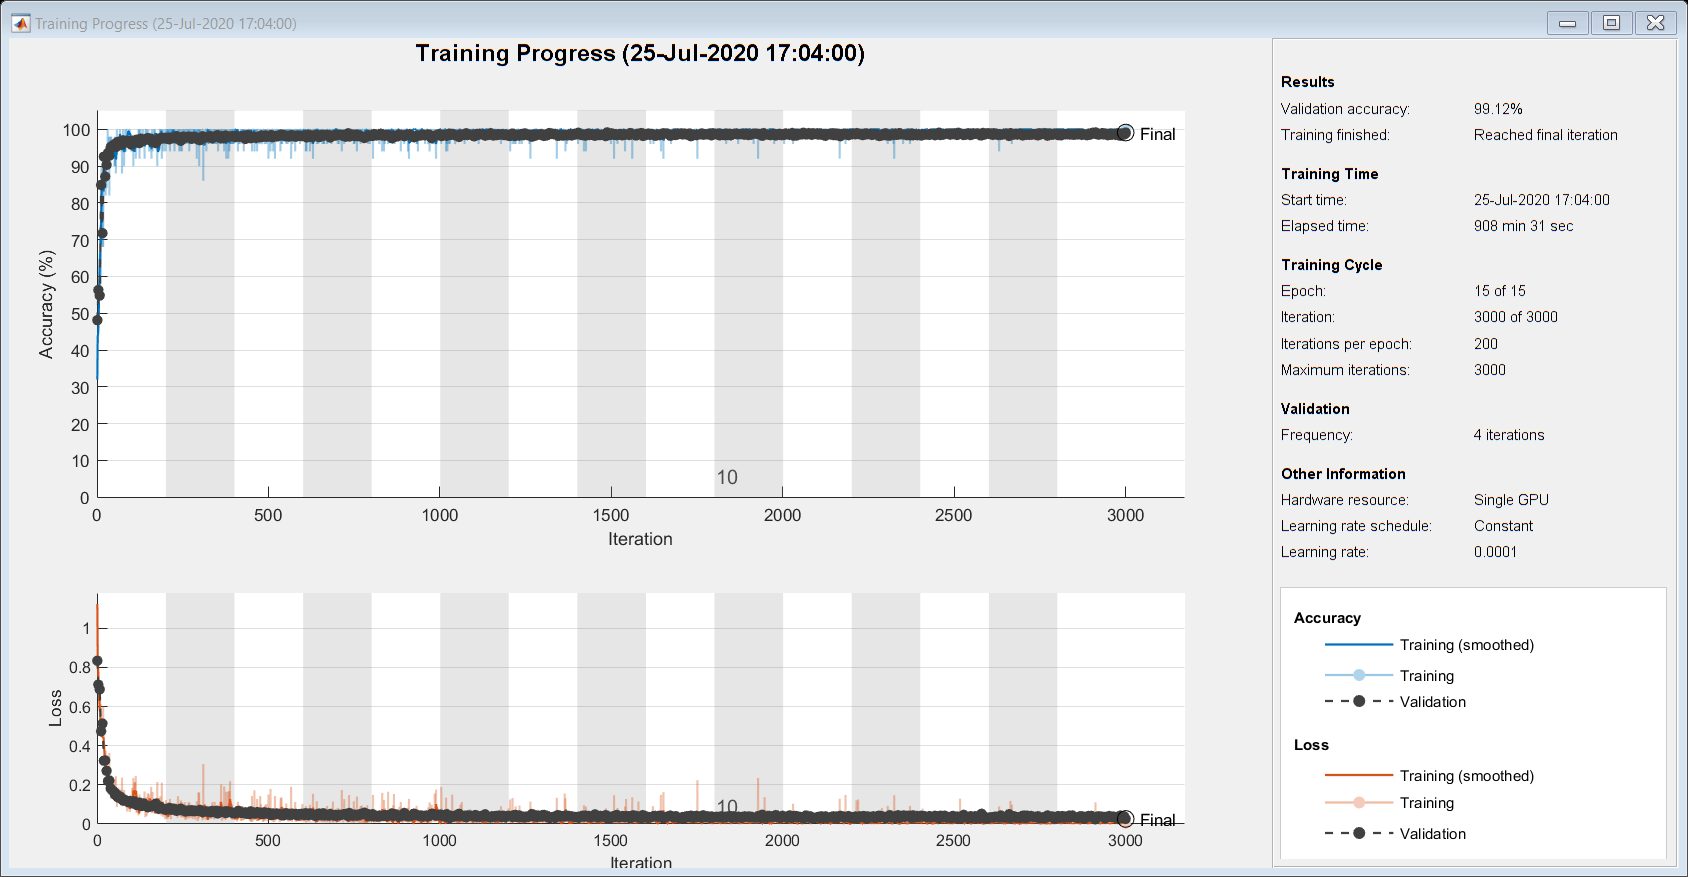



% Layer transfer
LayerGraph = layerGraph(improvedModel_2);
numClasses = 2; % number of classes

% create new fully connected layer with different number of classes
newFullyConnectedLayer = fullyConnectedLayer(numClasses, ...
    'Name','new_fc', ...
    'WeightLearnRateFactor',20, ...
    'BiasLearnRateFactor',20);

% create new classification layer
newClassLayer = classificationLayer('Name','new_classoutput');

% get names of current fcl & classification layer
fclName = LayerGraph.Layers(end-2).Name;
classLayerName = LayerGraph.Layers(end).Name;

% replace them with our new ones
LayerGraph = replaceLayer(LayerGraph,fclName,newFullyConnectedLayer);
LayerGraph = replaceLayer(LayerGraph,classLayerName ,newClassLayer);

% set training options for model
options = trainingOptions('sgdm', ...
    'MiniBatchSize',50, ...
    'MaxEpochs',15, ...
    'InitialLearnRate',1e-4, ... 
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',4, ...
    'Verbose',false, ...
    'ExecutionEnvironment',"auto", ...
    'Plots','training-progress');

% train the new network
improvedModelTransfer_2 = trainNetwork(augimdsTrain,LayerGraph,options);


% classify the images in our validation set
ValPred = classify(improvedModelTransfer_2, augimdsValidation);

ValidationActual = validationSet.Labels;
accuracy = mean(ValPred == ValidationActual); % get accuracy of validation set
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 99.12 %


### Improved Classifier 2 Test images

This code is to use the 1000 images from the Kaggle test dataset, to test Improved Classifier 2. And make a confusion matrix and ROC curve of Both cat and dog classes from the test images.

% set the path to our data folder
dataFolder = './data/test';
% create the variable that will hold our categories
categories = {'cat', 'dog'};

% create our image database for our test images
testimds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');

inputSize = improvedModel_2.Layers(1).InputSize; % get input image size

% use inputSize & colorPreprocessing to preprocess the images and store in
% an augmented image datastore
augtestimds = augmentedImageDatastore(inputSize(1:2),testimds, "ColorPreprocessing","gray2rgb");

% use our model to get the predictions on each image in our test set
[testPred,testScores] = classify(improvedModelTransfer_2,augtestimds);
% get the actual classification of each image
testActual = testimds.Labels;

% use mean to get the accuracy of our model
improved2_TestAccuracy = mean(testPred == testActual);
fprintf("The Test accuracy is: %.2f %%\n", improved2_TestAccuracy * 100);

The Test accuracy is: 99.40 %


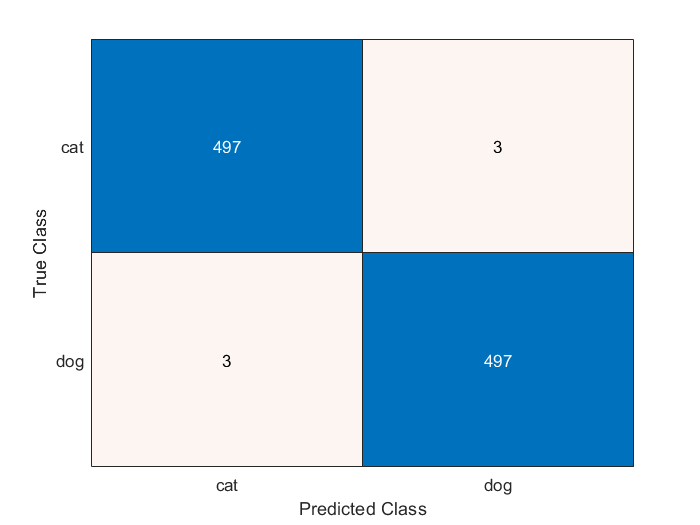


% make a confusion matrix out of the test images
improved2ConfusionMatrix = confusionchart(testActual,testPred);

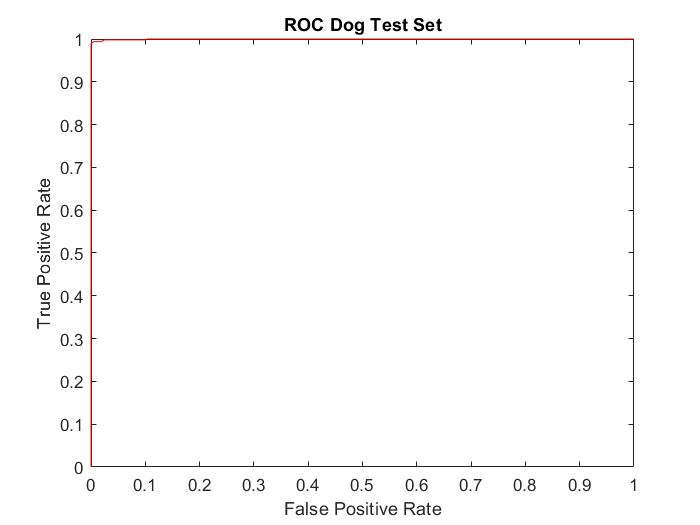


scoresDogTest = testScores(:,2); % get scores for dog images
scoresCatTest = testScores(:,1); % get scores for cat images

% roc graph for dog from test set
[FPRDogTest,TPRDogTest] = perfcurve(testActual,scoresDogTest,'dog');
plot(FPRDogTest,TPRDogTest, 'r-');
title('ROC Dog Test Set');
xlabel('False Positive Rate');
ylabel('True Positive Rate');

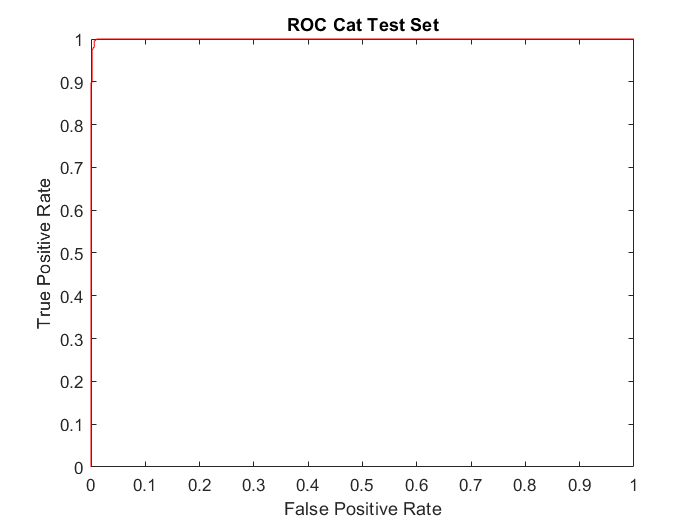


% roc graph for cat from Test Set
[FPRCatTest,TPRCatTest] = perfcurve(testActual,scoresCatTest,'cat');
plot(FPRCatTest,TPRCatTest, 'r-');
title('ROC Cat Test Set');
xlabel('False Positive Rate');
ylabel('True Positive Rate');